Computation Vision - Project 1 Report

Topic B:  Railway inspection using on-train cameras

Authors:

- David Marafuz Gaspar - 106541 - david.marafuz.gaspar@tecnico.ulisboa.pt

- Pedro Gaspar Monico - 106626 - pedro.monico@tecnico.ulisboa.pt

Supervisors:

- Prof. Alexandra Moutinho

- Eng. Alexandre Athayde

## Introduction

With the growth of railway systems in developed countries, and the recent expansion in developing nations, the safe and efficient operation of railway networks is paramount for passenger transport. To encourage the use of public transportation, it is very important to ensure the safety of the ridership. A critical aspect of this safety is ensuring that the track ahead is clear of obstructions, such as fallen trees, rocks, or debris, which could lead to catastrophic derailments. Traditionally, this inspection relies on periodic human patrols or trackside sensors, methods that can be time-consuming, costly, and lack the ability to provide real-time information to an oncoming train. Computer vision offers an alternative, as it can be automated without the high cost of continuous human resources.

This project aims to use image processing techniques to classify images of real railway tracks by detecting obstructions that could interfere with the passage of trains, ultimately enhancing the safety of this mode of transportation. The work will focus on several key problems: analyzing the images to characterize the appearance of the rails, and designing an algorithm to segment the image and isolate the rails. Subsequently, methods to determine whether the identified rail path is free of obstructions will be explored, not only checking if the rail itself is obstructed, but also detecting objects on the sides and in the area between the rails that could interfere with the train's path. The performance of the developed procedure will be quantitatively evaluated against our own annotated ground truth data using standard metrics.

This report is structured as follows [**FINISH THIS HERE**] Section 2 details the methodology and image processing tools employed in the development pipeline. Section 3 presents the results of the implemented algorithms and their performance analysis. Finally, Section 4 concludes the report with a summary of findings and a discussion of potential future improvements

% 1. Run checkpoint (from Deliverable folder)
aux_checkpoint

## Detection of Objects in Side and Inter-Rail Regions

The track detection methodology was robust and reliably detected obstructions on the rails. However, it did not detect obstructions along the sides of the track or in the inter-rail region. In the first iteration, the only misclassification was image p8.jpg: the rails appear clear, but large boulders on the right side of the image would obstruct the passage of a train, as they are very close to the track. Such obstructions could indirectly cause a derailment. The image is once again visualized:

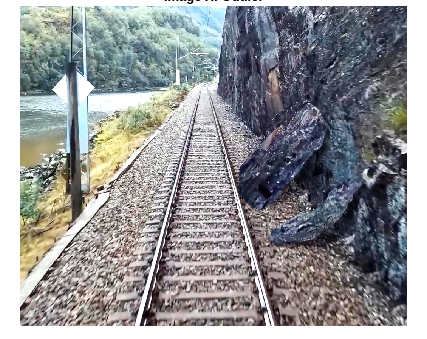

% Define the image file name
filename = 'p8.jpg'; 
folder = fullfile(pwd, 'Data'); 
filepath = fullfile(folder, filename);

% Load the image
img = imread(filepath);

% Display the image
imshow(img);

% Add title
title({'Image X: Outlier'}, 'FontSize', 10);

To address this limitation, we added an extra validation stage for images initially classified as clear, as described in the following steps:

- Rail regression

- Three-way region split

- Superpixel segmentation and Outlier detection

- Anomaly ratio for classification

### Rail Regression

Rail regression fits smooth curves to the left and right rails, enabling the subsequent definition of side and inter-rail regions for obstruction detection. The algorithm takes as input the preprocessed binary image obtained in the previous section. 

The endpoints of the extracted line segments are collected for each rail, forming two distinct point sets: one corresponding to the left rail and one to the right rail. A degree-2 polynomial is then fitted to each set using least-squares regression, modeling the rail's horizontal position as a function of the image row. The model takes the form:


$$x = p_1 y^2 + p_2 y + p_3$$


where $x
$ represents the horizontal coordinate, $y$ the row index, and $p_1, p_2, p_3$ the polynomial coefficients obtained via standard polynomial fitting techniques such as MATLAB's `polyfit` function.

The choice of a quadratic model is motivated by the perspective distortion present in railway images. Railway tracks appear to converge toward the horizon and may exhibit slight curvature, characteristics that a degree-2 polynomial captures more accurately than a simple linear model, while remaining computationally efficient and robust to noise. The output of this regression stage consists of the fitted polynomials, which define the left and right rail positions for any given row $y
$ within the image serving as the foundation for the subsequent analysis stage.

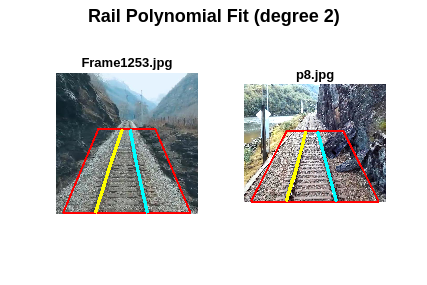

clear_idx = find(predicted_status == "Clear");

for k = 1:numel(clear_idx)
    i = clear_idx(k);
    
    % Get preprocessed binary image for this image
    bw_clean = images_otsu_dog_roi_clean{i};
    [h, w] = size(bw_clean);
    
    % Build ROI mask (trapezoid)
    roi_x = [ROI_BL_X*w, ROI_BR_X*w, ROI_TR_X*w, ROI_TL_X*w];
    roi_y = [h, h, ROI_TOP_Y*h, ROI_TOP_Y*h];
    roi_mask = poly2mask(roi_x, roi_y, h, w);
    
    % Call your auxiliary function
    [left_pts, right_pts, left_segments, right_segments, ...
     x_left_fit, x_right_fit, y_fit, p_left, p_right] = ...
        aux_rail_regression(bw_clean, roi_mask, n_strips, ...
        theta_min, theta_max, x_thresh);
    
    % Use outputs (e.g. store for later steps)
    rail_fits{i} = struct('left_pts', left_pts, 'right_pts', right_pts, ...
        'left_segments', {left_segments}, 'right_segments', {right_segments}, ...
        'x_left_fit', x_left_fit, 'x_right_fit', x_right_fit, ...
        'y_fit', y_fit, 'p_left', p_left, 'p_right', p_right, ...
        'roi_x', roi_x, 'roi_y', roi_y);
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.rail_fits = rail_fits;
results.filenames = filenames;

% Plot rail regression for clear images 1 and 2 only
plot_rail_regression(results, images, [1, 8]);

### Three-way region split

The three-way region split utilizes the fitted rail polynomials from the previous regression step to define three distinct regions of interest: left, middle, and right. These regions serve as the basis for subsequent superpixel-based anomaly detection, enabling targeted analysis of areas relevant to railway obstruction identification.

The function receives as input the image dimensions, the polynomial coefficients for the left and right rails, and three parameters: `ROI_TOP_Y`, `rail_padding`, and `pct_side`. After generating rail position maps, where for each row the horizontal positions of the left and right rails are computed using the fitted polynomials, a vertical mask is then applied to exclude the upper portion of the image, just like in the initial region of interest.

Since the rail trajectories are now known, we can take advantage of this information by creating an adaptive ROI that follows the track, rather than using a hardcoded region. This is achieved by defining a percentage of the image width to extend outward from each rail, specified by the parameter `pct_side`. The value of `pct_side` was empirically chosen as 10% based on preliminary observations. Additionally, the mask excludes a empirically chosen 20-pixel width corresponding to the rails themselves, under the assumption that the track area of interest lies adjacent to, rather than on, the rails.

The output of this stage consists of three logical masks, each of size $h\times w$, indicating the pixels belonging to the left, middle, and right regions, respectively. These masks are subsequently used to constrain superpixel analysis to each region independently, improving detection accuracy by focusing on region-specific characteristics.

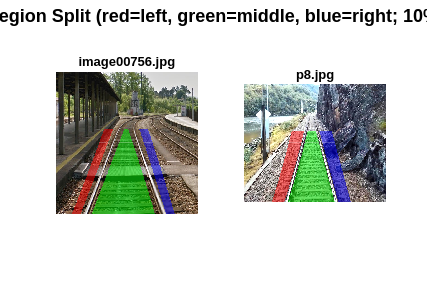

clear_idx = find(predicted_status == "Clear");

% Parameters
rail_padding = 20;
pct_side = 0.10;

N = length(images);
region_left   = cell(N, 1);
region_middle = cell(N, 1);
region_right  = cell(N, 1);

for k = 1:numel(clear_idx)
    i = clear_idx(k);

    [h, w, ~] = size(images{i});
    rf = rail_fits{i};
    p_left = rf.p_left;
    p_right = rf.p_right;

    [left_region, mid_region, right_region] = aux_three_way_regions(h, w, ...
        p_left, p_right, ROI_TOP_Y, rail_padding, pct_side);

    region_left{i}   = left_region;
    region_middle{i} = mid_region;
    region_right{i}  = right_region;
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.region_left   = region_left;
results.region_middle  = region_middle;
results.region_right  = region_right;
results.filenames = filenames;
results.roi_params = struct('pct_side', pct_side, 'rail_padding', rail_padding);

% Plot 3-way regions for clear images 4 and 8
plot_three_way_regions(results, images, [4, 8]);

### Superpixel segmentation and Outlier detection

The image is then converted to the LAB color space and segmented using the SLIC algorithm. Segmentation is performed on the full image to ensure that superpixel boundaries follow natural edges corresponding to objects, ballast, and other scene elements. The number of superpixels was set to 2500, a value that was empirically determined to provide the best trade-off between region size and computational performance. The SLIC compactness parameter was set to 10; lower compactness values yield more irregular boundaries that better adhere to object contours, which is desirable for accurately delineating potential obstacles.

For each superpixel that overlaps with one of the three regions of interest, a 6D feature vector is computed in LAB space, consisting of the median and standard deviation of the L, a, and b channels. This combination captures both color information and local texture characteristics. Features are computed exclusively from pixels lying within each region mask to ensure region-specific analysis.

The median was chosen over the mean for the central tendency measure because it is inherently more robust to outliers. Since the goal of this stage is precisely to detect anomalous objects that differ from the surrounding environment, using the mean would allow those same anomalies to skew the feature representation, potentially masking their presence.

Superpixel features from the left and right regions are pooled together, under the assumption that both sides consist of similar ground material. The median and interquartile range (IQR) are computed for each of the six feature dimensions across the pooled set. Each superpixel's feature vector is then normalized by subtracting the median and dividing by the IQR. The Euclidean distance of this normalized vector from the origin serves as the outlier score. Superpixels with a distance exceeding the Tukey fence defined as $Q3+1.5\times IQR$ are flagged as anomalous. The same process is done on the middle section.

For both the side regions and the middle region, an anomaly ratio is computed as the fraction of pixels belonging to anomalous superpixels relative to the total number of pixels in that region. These ratios are subsequently used in the final classification step to determine the presence of obstructions.

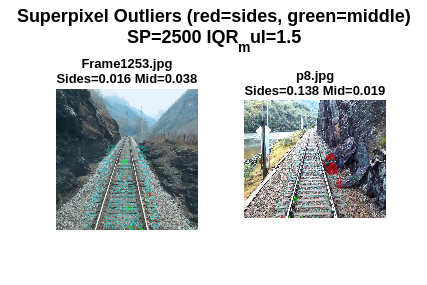

clear_idx = find(predicted_status == "Clear");

num_superpixels = 2500;
sp_compactness  = 10;
iqr_multiplier  = 1.5;

N = length(images);
anomaly_maps   = cell(N, 3);
anomaly_ratios = nan(N, 2);
sp_labels_all  = cell(N, 3);

for k = 1:numel(clear_idx)
    i = clear_idx(k);
    img = images{i};
    if size(img, 3) == 1
        img = repmat(img, [1 1 3]);
    end

    [anom_left, anom_mid, anom_right, sp_labels, r_sides, r_mid] = ...
        aux_superpixel_and_outliers(img, region_left{i}, region_middle{i}, region_right{i}, ...
        num_superpixels, sp_compactness, iqr_multiplier);

    anomaly_maps{i, 1} = anom_left;
    anomaly_maps{i, 2} = anom_mid;
    anomaly_maps{i, 3} = anom_right;
    anomaly_ratios(i, 1) = r_sides;
    anomaly_ratios(i, 2) = r_mid;
    sp_labels_all{i, 1} = sp_labels{1};
    sp_labels_all{i, 2} = sp_labels{2};
    sp_labels_all{i, 3} = sp_labels{3};
end

% Build minimal results struct for plotting
results.clear_idx = clear_idx;
results.region_left   = region_left;
results.region_middle = region_middle;
results.region_right  = region_right;
results.anomaly_maps  = anomaly_maps;
results.anomaly_ratios = anomaly_ratios;
results.sp_labels_all = sp_labels_all;
results.filenames = filenames;
results.sp_params = struct('num_superpixels', num_superpixels, 'iqr_multiplier', iqr_multiplier);

% Plot superpixel outliers for clear images 1 and 8
plot_superpixel_outliers(results, images, [1, 8]);

### Anomaly ratio for classification

This constitutes the final step of the secondary classification pipeline. It is important to recall that this stage is applied exclusively to images that were initially classified as "Clear", meaning that the tracks were successfully extracted by the first classification algorithm. This step examines the anomaly ratios computed for the side and middle regions. If the percentage of anomalous superpixels in either region exceeds 10%, the image is reclassified as "Obstructed". This threshold was deemed sufficient based on empirical observation: an image known to contain an obstruction exhibited an anomaly ratio of 14% on the side region. Thus, the anomaly ratios effectively indicate the presence of obstructions in the side or inter-rail regions that were not detected by the first-stage Hough-based method.

clear_idx = find(predicted_status == "Clear");

anomaly_percentage_thresh = 0.1;

final_status = aux_anomaly_classification(predicted_status, anomaly_ratios, anomaly_percentage_thresh);

% Build minimal results struct (for consistency; no plot for step 4)
results.clear_idx = clear_idx;
results.final_status = final_status;
results.anomaly_ratios = anomaly_ratios;
results.filenames = filenames;

% Final summary table (only images initially classified as Clear)
nClear = numel(clear_idx);
img_names_clear = cell(nClear, 1);
for k = 1:nClear
    i = clear_idx(k);
    [~, fname, ext] = fileparts(filenames{i});
    img_names_clear{k} = [fname ext];
end

% Ensure all table variables are column vectors with same number of rows
final_summary = table(...
    clear_idx(:), ...
    img_names_clear, ...
    predicted_status(clear_idx(:)), ...
    anomaly_ratios(clear_idx(:), 1), ...
    anomaly_ratios(clear_idx(:), 2), ...
    final_status(clear_idx(:)), ...
    'VariableNames', {'Image', 'Filename', 'InitialClass', 'SidesRatio', 'MiddleRatio', 'FinalClass'});

disp(final_summary);

    Image         Filename         InitialClass    SidesRatio    MiddleRatio     FinalClass 
    _____    __________________    ____________    __________    ___________    ____________

      2      {'Frame1253.jpg' }      "Clear"         0.015602      0.038199     "Clear"     
      3      {'Frame1291.jpg' }      "Clear"         0.011236    0.00020973     "Clear"     
      4      {'Frame1532.jpg' }      "Clear"         0.045853      0.071375     "Clear"     
      7      {'image00756.jpg'}      "Clear"       0.00062432      0.047166     "Clear"     
      8      {'image02293.jpg'}      "Clear"         0.018422      0.018295     "Clear"     
     10      {'image04925.jpg'}      "Clear"         0.012228      0.039727     "Clear"     
     11      {'image06026.jpg'}      "Clear"       

### Results

## Conclusions